# Querying and Setting the Zoom Level

## Example: Basic use of getImageZoomLevel and setImageZoomLevel

This example illustrates the use of `getImageZoomLevel` and `setImageZoomLevel` to query the zoom level, zoom in and out, and then display the entire image using the `"fit"` option.

First, display the image.

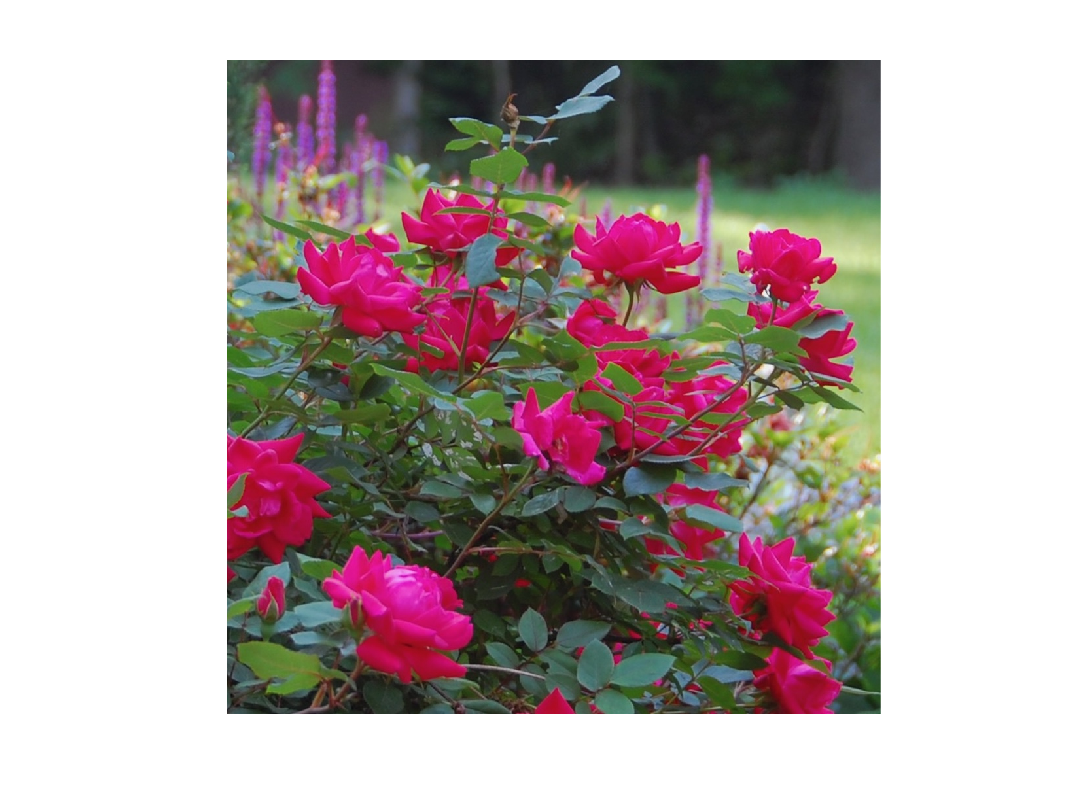

A = imread("roses-se.jpg");
imshow(A)

Query the zoom level.

level = getImageZoomLevel

level =    34.2667   34.2667


The two `level` values are the horizontal and vertical zoom levels. When displaying images using `imshow`, these are usually the same. They can be different if the axes `DataAspectRatio` is not `[1 1 1]`, or if the image `XData` and `YData` properties have been set to nondefault values. The horizontal and vertical zoom levels are often different if the `image` or `imagesc` function is used to display the image.

Zoom in to 100%.

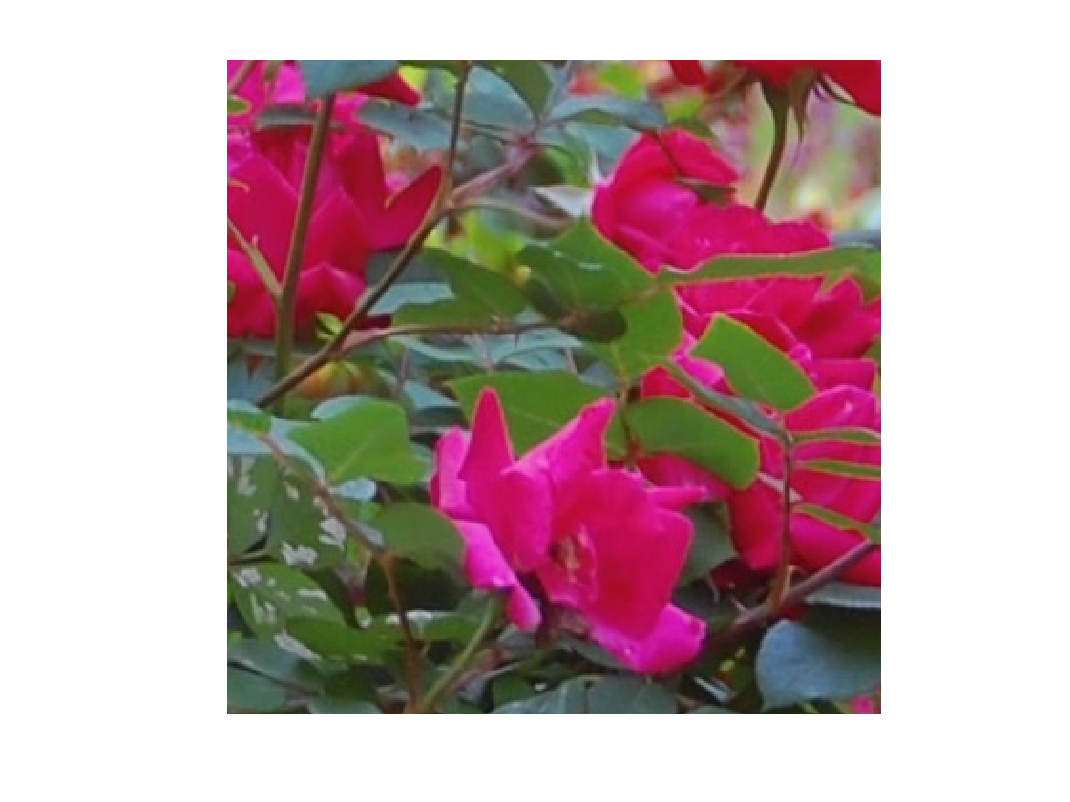

setImageZoomLevel(100)

The axes and figure size did not change, so now only the center portion of the image is visible.

Zoom in to 1000%

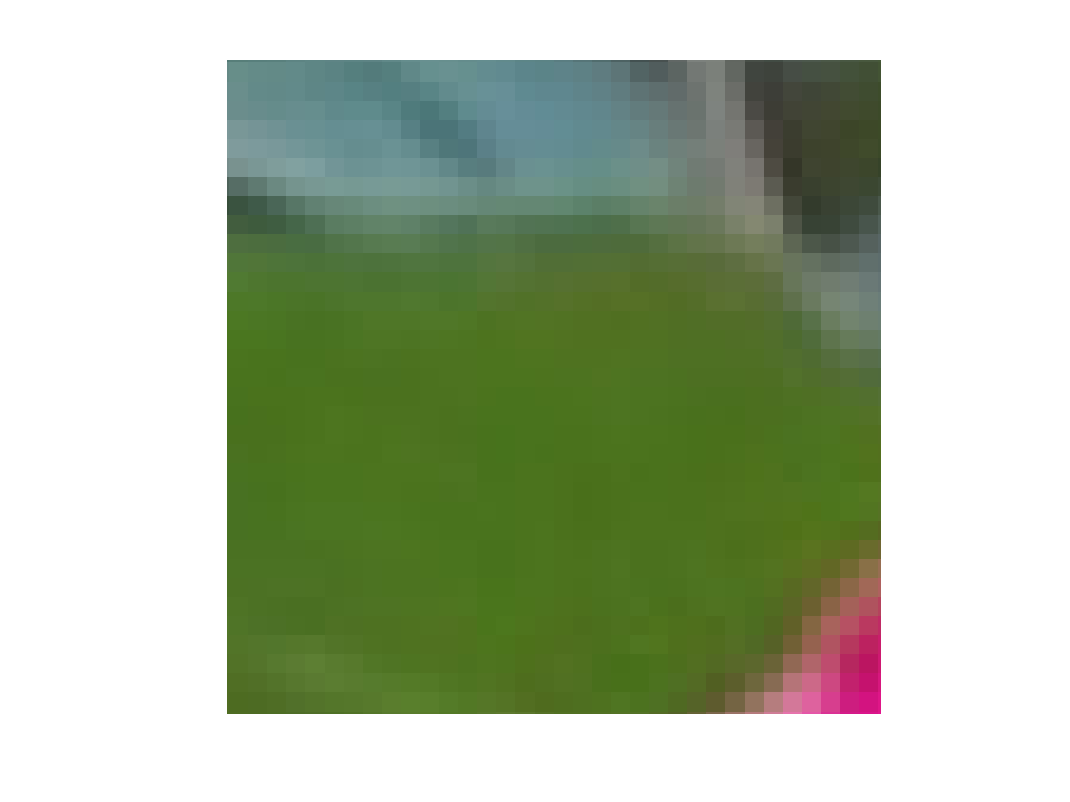

setImageZoomLevel(1000)

Now, individual pixels are clearly visible.

Use the `"fit"` option to once again view the entire image within the axes.

setImageZoomLevel("fit")

## Example: Unequal horizontal and vertical zoom levels

When using the function `imagesc` to display an image, the `DataAspectRatio` is usually not `[1 1 1]`, which means that the pixels are usually not square. Here is an example.

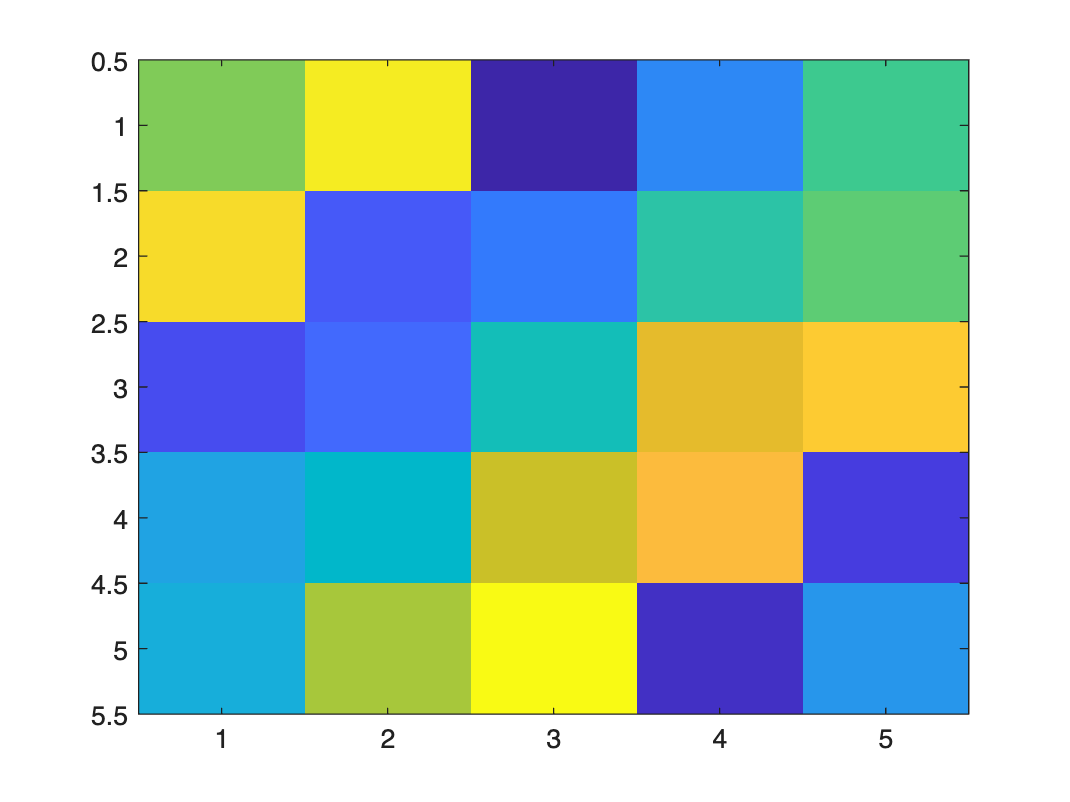

B = magic(5);
imagesc(B)

The pixels are a bit wider than they are tall. The function `getImageZoomLevel` shows the exact difference.

level = getImageZoomLevel

level = 1.0e+03 *

    8.6800    6.8533


You can make the pixels display as squares by passing in a scalar zoom level to `setImageZoomLevel`. The function will use that scalar to set both the horizontal and zoom levels to the same value.

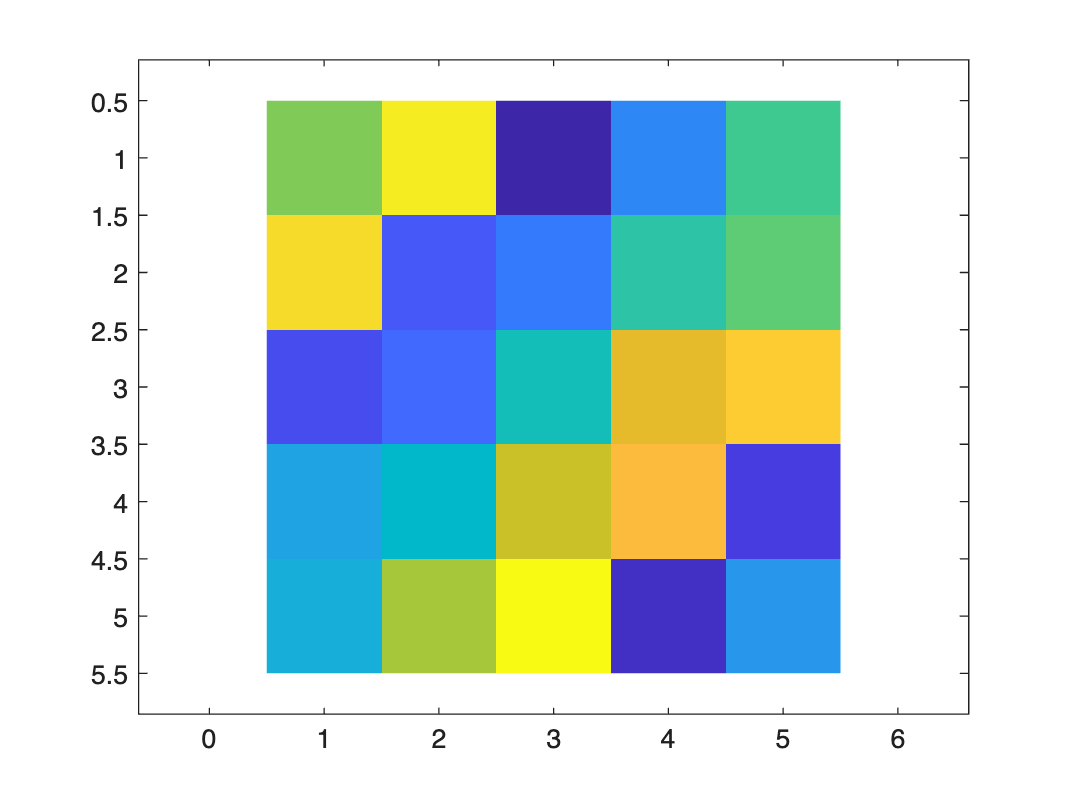

setImageZoomLevel(6000)